# **[2024년 1학기 확률 최적 제어] Monte Carlo 시뮬레이션 예제**

- **교과목** : 2024년 1학기 제어시스템특론

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수([gyunghoon.park@uos.ac.kr](http://gyunghoon.park@uos.ac.kr)) 

본 예제에서는 [Stanford University EE365](https://web.stanford.edu/class/ee365/index.html) 교과목의 [03. Probability and Monte Carlo](https://web.stanford.edu/class/ee365/lectures/mc.pdf) 강의 교안 중 7페이지에 수록된 Monte Carlo 시뮬레이션 예제를 구현하기 위해 제작되었습니다. 

**주의사항**

- 본 예제에서는 [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html)의 일부 함수를 사용하고 있습니다. 

- 본 예제는 MATLAB 2023b 버젼에서 작성되었습니다. 2023b 이상 버젼에서의 구동을 권장합니다.

#### 문제 설정

이번 문제에서는 IID이며 이항 분포(binomial distribution)를 따르는 $b_i \sim {\rm Bion}(0.4)$들로 구성된 $x:=(b_1,\dots,b_{50})$에 대하여, 다음 비선형 함수의 값을 Monte Carlo 시뮬레이션을 통해 수치적으로 도출하고자 합니다. 


$$f(x):={\bf Prob}\left( \sum_{i=1}^{25} b_i \geq 0.6 \sum_{i=1}^{50} b_i  \right)$$


#### 풀이

clc;
clear all;
close all;

일부 상수를 전역 변수로 설정합니다.

global sizeOfState;     sizeOfState = 50;
global sizeOfSim;       sizeOfSim = 10000;
global probIsOne;       probIsOne = 0.4;

필요한 변수들을 초기화합니다. 

x = zeros(sizeOfSim,sizeOfState);
sumF = 0;
estiamte = zeros(sizeOfSim,1);

여기서 `x(i,:)`는 $i$번째 샘플인 $x^{(i)}\in \mathbb{R}^{50}$를 의미하며,  `estimate(N)`은 $f(x)$의 Monte Carlo 추정치인 


$$\hat{e}^{(N)}:=\frac{1}{N}\sum_{i=1}^{N} f\big( x^{(i)} \big)$$


를 의미합니다. `sumF`는 위의 추정치를 계산하기 위한 $\sum_{i=1}^{N}f(x^{(i)})$를 저장하는 변수입니다.

이제 `sizeOfSim` 개의 샘플 $x^{(i)}\in \mathbb{R}^{50}$를 얻고, `estimate(N)`을 계산합니다. 이 과정에서 `Statistics and Machine Learning Toolbox`에서 제공하는 함수인 `binornd`를 사용하여 $b_i\sim {\rm Bino}(0.4)$를 얻습니다.

for N = 1:sizeOfSim
    x(N,:) = zeros(1, sizeOfState);
    for k = 1:sizeOfState
        x(N,k) = binornd(1, probIsOne);         
    end
    sumF = sumF + computeProb(x(N,:));
    estimate(N) = (1/N)*sumF;
end

(지역 함수인 `computeProb` 함수는 `x(N,:)` 값에 따라 `0` 혹은 `1`을 return합니다.)

#### 결과 출력

이제 결과인 `estimate(N)`을 `N`에 대해 그려보면 다음과 같습니다.

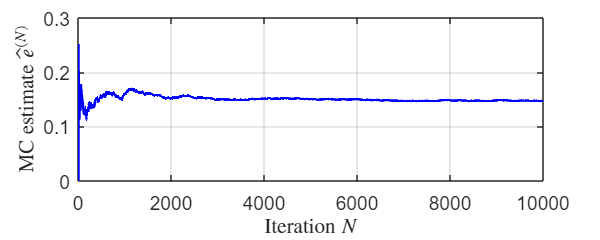

f = figure;
f.Position = [100 100 500 200];

plot(1:sizeOfSim, estimate, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Iteration $N$', 'Interpreter', 'latex');
ylabel('MC estimate $\hat{e}^{(N)}$', 'Interpreter', 'latex');
set(gca, 'fontsize', 12);

#### 지역 함수 정의

function v = computeProb(xi)
    global sizeOfState;
    global probIsOne;
    sumBLower = sum(xi(1:sizeOfState/2));
    sumB = sum(xi(1:sizeOfState));    
    if (sumBLower >= (1-probIsOne)*sumB)
        v = 1;
    else
        v = 0;
    end
end